hold on
grid on
x = [0.2 0.4 0.6 0.8 1.0 1.2 1.4];
y = [242.7 404.5 632.3 801.0 921.1 1003.1 1028.3];
point = scatter(x,y);
xlim([0.1;1.6])
coeff_1 = polyfit(x,y, 2)

coeff_1 = 	1.0e+03 *

   -0.4492    1.4049   -0.0456


y1 = 0;
xi = min(0):0.1:max(1.6)

xi =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000


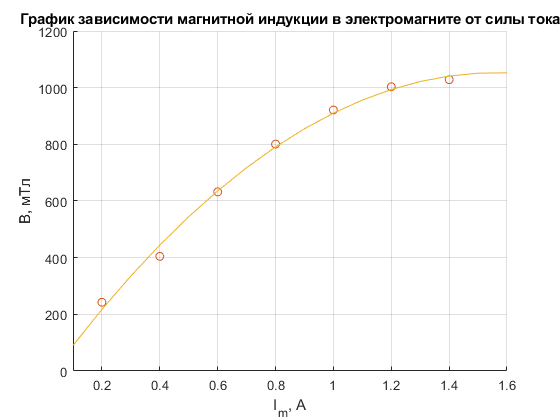

for k=0:2
    y1 = y1 + coeff_1(2-k+1) * xi.^k;
end
gr_1 = plot(xi, y1); 
title("График зависимости магнитной индукции в электромагните от силы тока")
xlabel('I_m, A')
ylabel('B, мТл')
hold off